# Test Controllers

clear
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

#### Load DGU Network parameters from file and initialize the class for the DGU Network

- Constant variables for the rest of the analysis:

clear
length_sim = 35;
simStart = 1;
utils = utilityFunctions; % utility function class
sim = SimFunctionsPnP; % simulation function class
filename = 'config_DGU_1.txt'; % Initial DGU Network
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0



activeDGU = 1:nb_subsystems; % all DGU are active

#### Define the resistor values connecting the DGUs i.e. interconnection strengths.

Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8;

Make the interconnection between DGU 3 and DGU 6 variable:

Rij_mat(3,6) =0.8

Rij_mat =          0    1.7500         0         0         0         0
         0         0    3.5000    1.7500         0         0
         0         0         0         0    2.8000    0.8000
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0


Rij_mat = Rij_mat + tril(Rij_mat',1); % symmetric matrix for undirected graph
%% Instantiate DGU NETWORK
dguNet = DGU_network(nb_subsystems);
dguNet = dguNet.setConnectionsGraph(Rij_mat);
dguNet = dguNet.setActiveDGU(activeDGU);

- Plot the Graph describing the Network

plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("DGUs interconnection graph")

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.95, 50.2, nb_subsystems); % references
Il = linspace(2.5, 7.5, nb_subsystems);
% set Electrical parameters
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end
dguNet = dguNet.initDynamics();

#### Test the Passivity controller, $\Delta$ Formulation of constraints to converge to references

delta_config = true; % Delta-Formulation of DGU Network
dguNet = dguNet.compute_Ref_Constraints(delta_config); % constraints in delta formulation
control_type = "PASSIVITY";
config = "DISTRIBUTED";
dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312

minimum eigenvalue of dissipation rate 8.95e-01 


ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612

minimum eigenvalue of dissipation rate 9.97e-02 


ans = "K3"

   -0.4021   -0.1549



ans = "P3"

    8.3946    0.6205
    0.6205    0.3201

minimum eigenvalue of dissipation rate 2.36e-01 


ans = "K4"

   -0.0062   -0.0945



ans = "P4"

    4.1335    0.6268
    0.6268    5.5436

minimum eigenvalue of dissipation rate 8.59e-02 


ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810

minimum eigenvalue of dissipation rate 1.32e+00 


ans = "K6"

   -0.0567   -0.0992



ans = "P6"

    5.2750    0.7658
    0.7658    1.7112

minimum eigenvalue of dissipation rate 3.36e-01 


passivity = true; % set passivity boolean to true
[x0, ~, ~, ~] = utils.tuningParam(dguNet, delta_config, passivity) % initial parameters definition

Qi and Ri found to guarantee asympt. stabilityof the global system 


x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


[X,U] = sim.sim_DGU_distributed(x0, length_sim, dguNet, dguNet.Ki);
error_pass = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_pass = 5.1450

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU);

#### Evaluate Passivity controller by comparing it to LQR

config = "GENERAL";
control_type = 'LQR';
Ad = dguNet.global_sysd.A; Bd = dguNet.global_sysd.B; 
Q = eye(size(Ad,1)); R = eye(size(Bd,2));
disp("LQR controller Gain");

LQR controller Gain


[Klqr, Pinf, ~] = dlqr(Ad, Bd, Q,R)

Klqr =     0.0459    0.0946    0.0144    0.0015    0.0023    0.0002    0.0072    0.0006    0.0005    0.0000    0.0013    0.0001
    0.0248    0.0016    0.0254    0.1040    0.0075    0.0007    0.0228    0.0018    0.0023    0.0002    0.0051    0.0004
    0.0034    0.0002    0.0064    0.0007    0.0254    0.1017    0.0031    0.0002    0.0154    0.0011    0.0297    0.0024
    0.0089    0.0006    0.0166    0.0017    0.0026    0.0002    0.0458    0.0973    0.0005    0.0000    0.0014    0.0001
    0.0005    0.0000    0.0015    0.0001    0.0114    0.0010    0.0005    0.0000    0.0519    0.0954    0.0077    0.0006
    0.0015    0.0001    0.0037    0.0004    0.0249    0.0023    0.0014    0.0001    0.0087    0.0006    0.0357    0.0964


Pinf =     5.7840    0.3284    1.3453    0.1353    0.2215    0.0193    0.6815    0.0534    0.0479    0.0032    0.1242    0.0095
    0.3284    1.0310    0.0887    0.0089    0.0143    0.0012    0.0441    0.0035    0.0030    0.0002    0.0079    0.0006
    1.3453    0.0887    2.7571    0.1882    0.4192    0.0373    1.2571    0.1005    0.1320    0.0092    0.2847    0.0224
    0.1353    0.0089    0.1882    1.0306    0.0420    0.0037    0.1259    0.0100    0.0128    0.0009    0.0279    0.0022
    0.2215    0.0143    0.4192    0.0420    3.0079    0.1897    0.2017    0.0157    0.9741    0.0697    1.8711    0.1511
    0.0193    0.0012    0.0373    0.0037    0.1897    1.0280    0.0175    0.0014    0.0866    0.0062    0.1683    0.0135
    0.6815    0.0441    1.2571    0.1259    0.2017    0.0175    4.8862    0.3241    0.0438    0.0030    0.1120    0.0086
    0.0534    0.0035    0.1005    0.0100    0.0157    0.0014    0.3241    1.0359    0.0033    0.0002    0.0086    0.0007
    0.0479    0.0030    0

[Xlqr,Ulqr] = sim.sim_global_DGU(x0, length_sim, dguNet, -Klqr);
error_lqr = utils.tracking_error(Xlqr,Ulqr,config,dguNet,activeDGU)

error_lqr = 4.5552

dguNet.plot_DGU_system(Xlqr,Ulqr, config, control_type, dguNet, simStart, activeDGU)

- Compute the suboptimality index $\frac{e_{pbc} - e_{lqr}}{e_{lqr}}$  where the tracking error is defined as:

$e=\sqrt{\sum_{k=0}^{T} \sum_{i=1}^{6}\left(\Delta V_{i}^{k^{2}}+\Delta I_{i}^{k^{2}}+\Delta u_{i}^{k^{2}}\right)}$ is computed where $\Delta V_{i}^{k}=V_{i}^{k}-V_{r_{i}}, \Delta I_{i}^{k}=I_{i}^{k}-I_{r_{i}}$, $\Delta u_{i}^{k}=u_{i}^{k}-u_{r_{i}}, T$ is the simulation time, $I_{r_{i}}$ and $u_{r_{i}}$ are the steady state values of the corresponding variables. 

suboptimality_index = (error_pass - error_lqr)/error_lqr

- Compare cost of the 2 methods

sprintf("Cost using the passive controller = %d", utils.compute_QR_cost(X,U,Q,R,"DISTRIBUTED", dguNet.Xref , dguNet.Uref))
sprintf("Cost using the LQR controller = %d", utils.compute_QR_cost(Xlqr,Ulqr,Q,R,"GENERAL",dguNet.Xref , dguNet.Uref))

For the LQR controller, the cost can also be computed as $J_\infty = x_0^T P_\infty x_0$

dx0 = vertcat(x0{:}) - vertcat(dguNet.Xref{:});
sprintf("Cost of LQR controller using closed form solution = %d", dx0'*Pinf*dx0)

#### Test MPC without reconfigurable terminal ingredients (also $\Delta$ Formulation)

$\mathbb{X}_f^i = \{ x_i \in \mathbb{R}^m |  V_f^i(x_i) \leq \alpha_i\}$ where $V_f^i(x_i) = x_i^T P_i x_i$ and $\alpha_i^+ = \alpha_i + x_{Ni}^T(N) \Gamma_i 
 x_{Ni} (N)$

- **Using Lyapunov terminal constraints to get **$\alpha_i$

dguNet_delta = dguNet; % make a copy of actual DGU network for delta formulation
delta_config = true;
passivity = false; % set passivity boolean to false
[x0_delta, Q_Ni, Ri] = utils.tuningParam(dguNet_delta, delta_config,passivity);
dguNet_delta = dguNet_delta.compute_Ref_Constraints(delta_config); % constraints in delta formulation

Compute $P_i$, $\Gamma_i$, $\alpha_i$

[dguNet_delta, Gamma_Ni, alpha_i] = offlineComputeTerminalSet(Q_Ni, Ri, dguNet_delta);

ans = "Local feedback control laws K_N1"

   1.0e-03 *

         0         0    0.3814         0



ans = "Local feedback control laws K_N2"

   1.0e-03 *

    0.5724    0.0000         0         0    0.2862    0.0000    0.5724    0.0000



ans = "Local feedback control laws K_N3"

    0.0003   -0.0000         0         0    0.0003   -0.0000    0.0011         0



ans = "Local feedback control laws K_N4"

   1.0e-03 *

    0.4615   -0.0000         0         0



ans = "Local feedback control laws K_N5"

   1.0e-03 *

    0.2591         0         0         0



ans = "Local feedback control laws K_N6"

    0.0010         0         0         0



sprintf("Initial terminal set constrait alpha = %d", alpha_i)

ans = "Initial terminal set constrait alpha = 1.205337e-01"

alpha = alpha_i*ones(nb_subsystems,1); % same alpha for every subsystem @ beginning
control_type = "MPC with offline computation of terminal ingredients";
config = "DISTRIBUTED";

Simulate system with online MPC and $\alpha_i$ update outside of the MPC

[Xdelt, Udelt, alphaEvolution] = sim.mpc_sim_DGU_delta(@mpc_delta_admm, x0_delta, length_sim, dguNet_delta,...
                         alpha, Q_Ni, Ri, Gamma_Ni);

--INFO: Using controller mpc_delta_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 1.095222e+00 and number of iterations 96 
---- Simulation step 2 ---- 
Time elapsed to converge 1.114739e+00 and number of iterations 95 
---- Simulation step 3 ---- 
Time elapsed to converge 1.329938e+00 and number of iterations 115 
---- Simulation step 4 ---- 
Time elapsed to converge 2.475708e+00 and number of iterations 218 
---- Simulation step 5 ---- 
Time elapsed to converge 2.073658e+00 and number of iterations 184 
---- Simulation step 6 ---- 
Time elapsed to converge 1.753867e+00 and number of iterations 158 
---- Simulation step 7 ---- 
Time elapsed to converge 1.457215e+00 and number of iterations 132 
---- Simulation step 8 ---- 
Time elapsed to converge 1.185463e+00 and number of iterations 107 
---- Simulation step 9 ---- 
Time elapsed to converge 9.329801e-01 and number of iterations 84 
---- Simulation step 10 ---- 
Time elapsed to converge 6.932759e-01 and number of ite

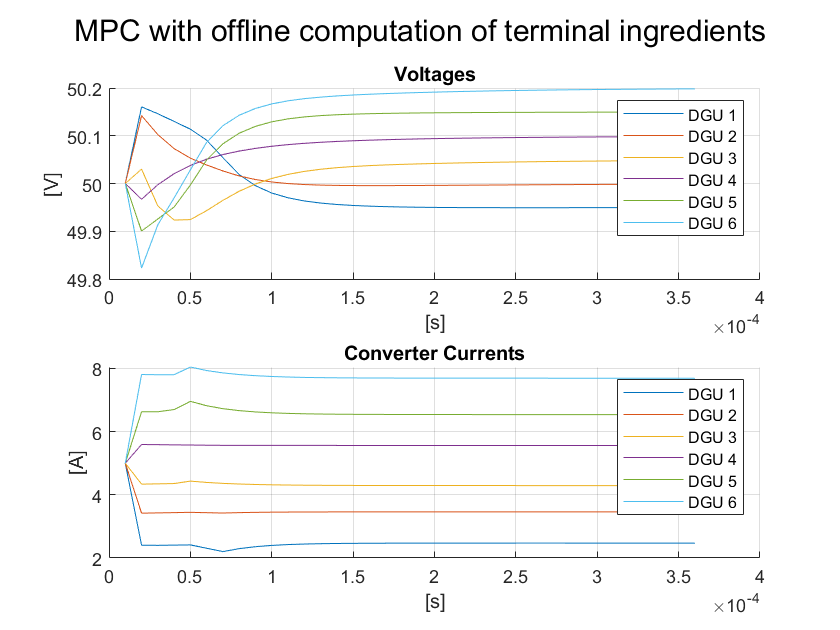

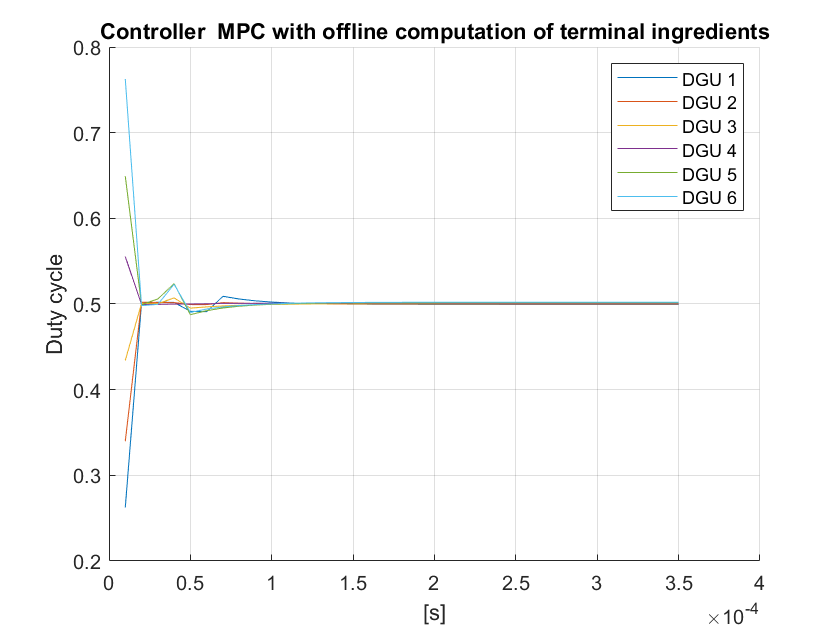

dguNet.plot_DGU_system(Xdelt,Udelt, config, control_type, dguNet, simStart, activeDGU)

One can also plot the evolution of the terminal set throughout the simulation

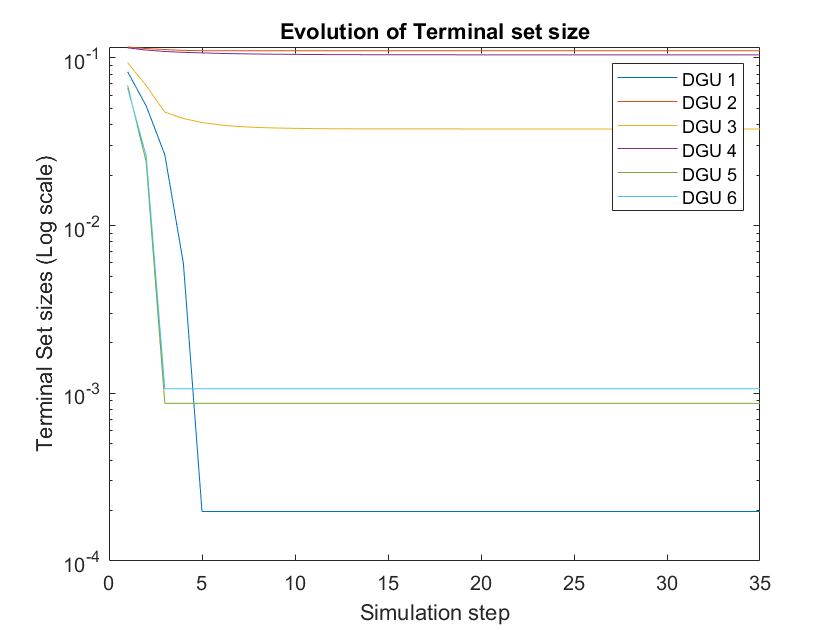

alphaEvolArray = cell2mat(alphaEvolution);
lgd = "DGU " + string(dguNet.activeDGU);
figure()
semilogy(abs(alphaEvolArray(dguNet_delta.activeDGU, :)'));
hold on
title("Evolution of Terminal set size")
xlabel("Simulation step");
ylabel("Terminal Set sizes (Log scale)")
legend(lgd);
hold off

- Compute the tracking error for the online distributed MPC with offline distributed initial terminal set synthesis

error_mpc_1 = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_mpc_1 = 5.1450

#### Test MPC for reference tracking with reconfigurable terminal ingredients (online)

Not in $\Delta$ Formulation

delta_config = false;
dguNet = dguNet.compute_Ref_Constraints(delta_config);

Obtain $K_i$ and $P_i$ from passivity, terminal set constraints directly implemented in the MPC

dguNet = sim.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312

minimum eigenvalue of dissipation rate 8.95e-01 


ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612

minimum eigenvalue of dissipation rate 9.97e-02 


ans = "K3"

   -0.4021   -0.1549



ans = "P3"

    8.3946    0.6205
    0.6205    0.3201

minimum eigenvalue of dissipation rate 2.36e-01 


ans = "K4"

   -0.0062   -0.0945



ans = "P4"

    4.1335    0.6268
    0.6268    5.5436

minimum eigenvalue of dissipation rate 8.59e-02 


ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6916
    4.6916    1.6810

minimum eigenvalue of dissipation rate 1.32e+00 


ans = "K6"

   -0.0567   -0.0992



ans = "P6"

    5.2750    0.7658
    0.7658    1.7112

minimum eigenvalue of dissipation rate 3.36e-01 


config = "DISTRIBUTED";
control_type = "MPC with terminal ingredients online computation";
passivity = true;
[x0, Q_Ni, Ri, ~] = utils.tuningParam(dguNet, delta_config, passivity)

Qi and Ri found to guarantee asympt. stabilityof the global system 


x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {8×8 double}    {4×4 double}    {4×4 double}    {4×4 double}


Ri = 1×6 cell array
    {[0.8616]}    {[4.5694]}    {[3.2974]}    {[3.6652]}    {[0.7612]}    {[3.1591]}


[X,U, alphaEvol] = sim.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, length_sim, dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 ---- Simulation step 1 ---- 
Time elapsed to converge 3.046181e+00 and number of iterations 61 
---- Simulation step 2 ---- 
Time elapsed to converge 2.431797e+00 and number of iterations 50 
---- Simulation step 3 ---- 
Time elapsed to converge 2.492168e+00 and number of iterations 50 
---- Simulation step 4 ---- 
Time elapsed to converge 2.973180e+00 and number of iterations 50 
---- Simulation step 5 ---- 
Time elapsed to converge 2.120191e+00 and number of iterations 44 
---- Simulation step 6 ---- 
Time elapsed to converge 2.078869e+00 and number of iterations 44 
---- Simulation step 7 ---- 
Time elapsed to converge 2.404933e+00 and number of iterations 50 
---- Simulation step 8 ---- 
Time elapsed to converge 2.212663e+00 and number of iterations 44 
---- Simulation step 9 ---- 
Time elapsed to converge 2.110313e+00 and number of iterations 44 
---- Simulation step 10 ---- 
Time elapsed to converge 2.308058e+00 and number of 

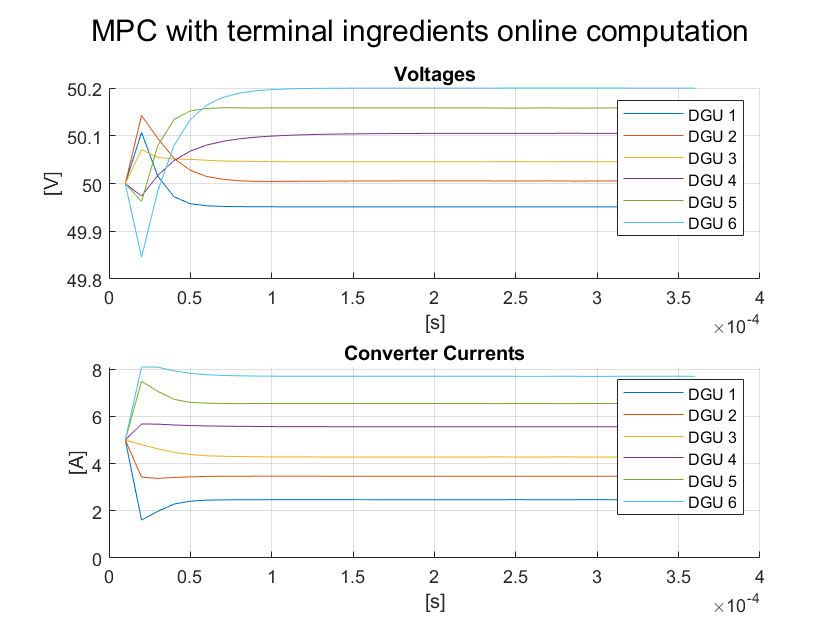

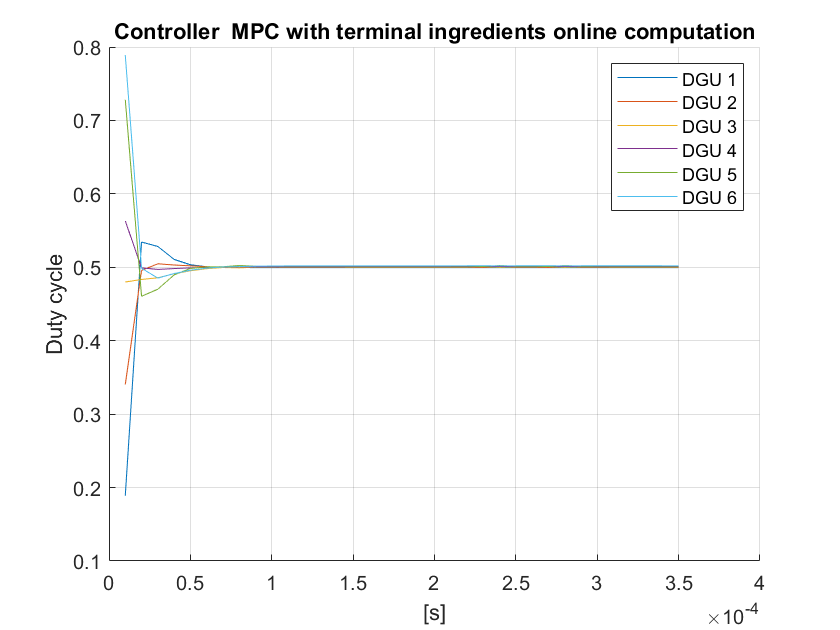

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart,activeDGU); % plot results

One can also plot the evolution of the terminal set throughout the simulation

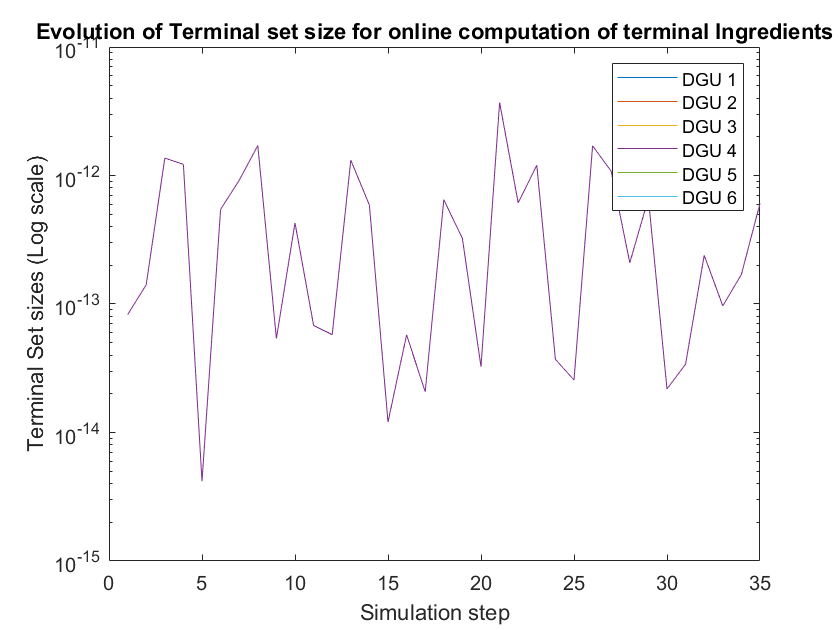

alphaEvolArr = cell2mat(alphaEvol);
lgd = "DGU " + string(dguNet.activeDGU);
figure()
semilogy(abs(alphaEvolArr(dguNet.activeDGU, :)'));
hold on
title("Evolution of Terminal set size for online computation of terminal Ingredients")
xlabel("Simulation step");
ylabel("Terminal Set sizes (Log scale)")
legend(lgd);
hold off

- Compute the tracking error for the online MPC with reconfigurable terminal ingredients

error_mpc_2 = utils.tracking_error(X,U,config,dguNet,activeDGU)

error_mpc_2 = 4.7889